ts=0.5;
fs=1/ts

fs = 2

N=512;
k=0:N-1;
td=k*ts;
p0=70;
f0=fs/6;%cumpliendo el teorema de nyquist
w=2*pi*f0

w = 2.0944

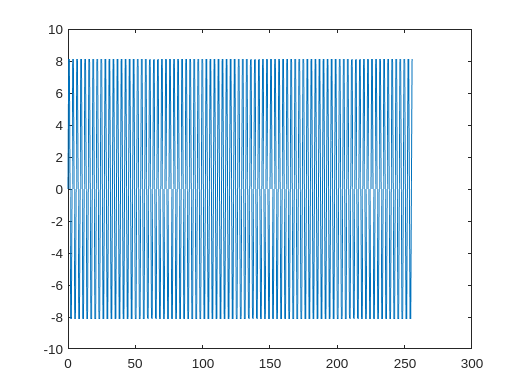

A=15;
x_n=(A*w)/3.35*sin(w*td);
plot(td,x_n)

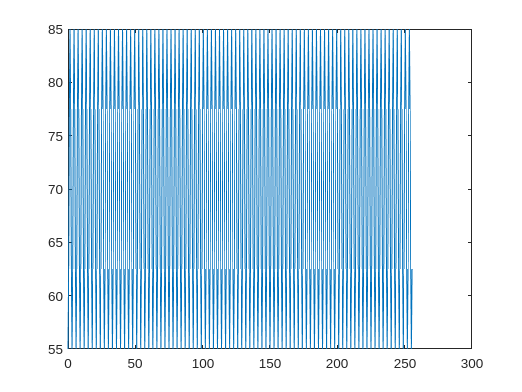

p_n=p0-A*cos(w*td);
figure
plot(td,p_n)

b=30%cm distancia entre robots o markers de la base del triangulo isosceles

b = 30

a=sqrt(p_n.^2+ (b/2)^2);%lados iguales del triangulo isosceles
h=p_n;
alpha123=asin(h./a);
alpha312=asin(b/2./a);
alpha231=pi-alpha123-alpha312;
